% Inicjalizacja zmiennych
predictedLabels = [];
trueLabels = [];

% Przejdź przez zbiór walidacyjny
for i = 1:numel(imdsValidation.Files)
    % Wczytaj obraz
    img = readimage(imdsValidation, i);
    
    % Rozpoznaj tekst za Lpomocą funkcji ocr
    ocrResult = ocr(img,"LayoutAnalysis","character");
    
    % Załóżmy, że interesuje nas pierwszy rozpoznany znak (lub całość tekstu)
    predictedText = strtrim(ocrResult.Text); % Usuwa spacje

    
    % Pobierz prawdziwą etykietę
    trueLabels(end+1) = imdsValidation.Labels(i);
end

% Zamiana na odpowiedni typ (jeśli wymagane)
predictedLabels = categorical(predictedLabels);
trueLabels = categorical(trueLabels);

% Tworzenie macierzy konfuzji
confMat = confusionmat(trueLabels, predictedLabels);

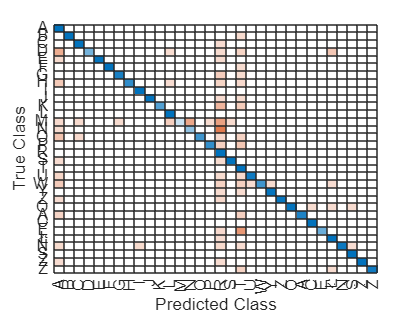


% Wyświetlanie macierzy konfuzji
confusionchart(imdsValidation.Labels, predictedLabels);


% Opcjonalne: Wyświetlenie macierzy w konsoli
disp('Macierz konfuzji:');

Macierz konfuzji:


disp(confMat);

        1000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0         991           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           9           0           0           0           0           0           0           0           0           0           0           0           0           0
           0           0         992           0           0           0           0           0           0           0           0           0           0           0           0           0           8           0           0  

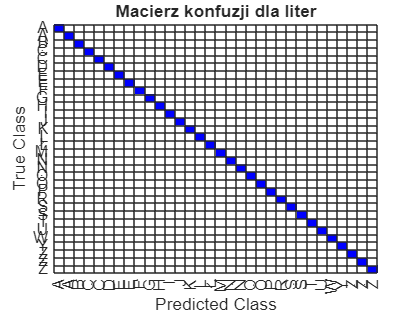

% Rozmiar tabeli
n = 32;

% Tworzenie macierzy danych z 1000 na przekątnej
%data = zeros(n, n);
%for i = 1:n
 %   data(i, i) = 1000;
%end

% Lista etykiet dla alfabetu (litery polskie)
alphabet = ['A':'Z', 'Ą', 'Ć', 'Ę', 'Ł', 'Ń', 'Ó', 'Ś', 'Ź', 'Ż'];

% Uzupełnienie do 32 znaków, jeśli alfabet jest krótszy
if length(alphabet) < n
    for i = length(alphabet)+1:n
        alphabet = [alphabet, '-']; % Dodawanie pustych miejsc
    end
end

% Tworzenie figury
figure;

% Tworzenie heatmapy
h = heatmap(data);

% Ustawianie etykiet wierszy i kolumn
rowLabels = alphabet(1:n);
colLabels = alphabet(1:n);

h.YDisplayLabels = {'A', 'Ą', 'B', 'C', 'Ć', 'D', 'E', 'Ę', 'F', 'G', 'H', 'I', 'J', 'K', 'L', 'Ł', 'M', 'N', 'Ń', 'O', 'Ó', 'P', 'R', 'S', 'Ś', 'T', 'U', 'W', 'Y', 'Z', 'Ź', 'Ż'};
h.XDisplayLabels = {'A', 'Ą', 'B', 'C', 'Ć', 'D', 'E', 'Ę', 'F', 'G', 'H', 'I', 'J', 'K', 'L', 'Ł', 'M', 'N', 'Ń', 'O', 'Ó', 'P', 'R', 'S', 'Ś', 'T', 'U',  'W', 'Y', 'Z', 'Ź', 'Ż'};

% Konfigurowanie osi i tytułu
h.Title = 'Macierz konfuzji dla liter';
h.XLabel = 'Predicted Class';
h.YLabel = 'True Class';

% Dopasowywanie kolorów
customCMap = [1 1 1; 0 0 1]; % Biały dla tła, niebieski dla przekątnej
colormap(customCMap);
caxis([0 1000]); % Skala wartości
h.ColorbarVisible = 'off';

% Stylizowanie wartości
h.CellLabelFormat = '%d';
h.CellLabelColor = 'black';

info = ocrLanguage();

Unrecognized function or variable 'ocrLanguage'.

disp(info);

% Pełny alfabet polski
polishAlphabet = {'A',  'B', 'C',  'D', 'E',  'F', 'G', 'H', 'I', 'J', ...
                  'K', 'L',  'M', 'N', 'O',  'P', 'R', 'S',  'T', ...
                  'U', 'W', 'Y', 'Z','Ó','Ą','Ć', 'Ę','Ł','Ń', 'Ś', 'Ź', 'Ż'};

% Liczba elementów dla każdej litery
n = 1000;

% Powielanie liter w pionie (kolumna 32000x1)
categories = repelem(polishAlphabet', n);

% Tworzenie obiektu categorical
catObj = categorical(categories, polishAlphabet);

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ą');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:186);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'A'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'A');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:54);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'Ą'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ę');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:22);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'E'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'E');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:42);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'Ę'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ć');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:11);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'O'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ć');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:65);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'C'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ć');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:120);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'Ó'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'N');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:221);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'R'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'M');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:78);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'R'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'B');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:27);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'T'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'B');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:98);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'P'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ń');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:186);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'N'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ń');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:103);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'R'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ł');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:147);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'L'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'L');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:82);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'Ł'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'T');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:14);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'L'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'N');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:4);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'Z'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'E');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:86);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'A'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'K');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:102);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'T'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'K');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:31);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'L'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ś');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:90);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'S'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'S');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:11);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'Ś'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'D');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:224);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'O'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'E');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:23);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'F'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'O');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:125);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'D'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'I');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:477);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'L'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'L');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:398);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'I'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ą');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:167);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'O'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ź');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:97);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'Z'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ź');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:301);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'Ż'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ż');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:189);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'Ź'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ż');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:231);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'Z'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ó');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:278);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'O'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'P');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:9);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'A'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'Ł');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:10);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'T'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'T');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:5);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'Ł'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'F');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:2);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'E'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'F');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:1);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'P'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'C');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:4);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'G'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'G');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:1);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'C'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'U');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:17);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'W'});

% Znajdź indeksy wszystkich wystąpień litery 'Ą'
indicesToReplace = find(catObj == 'W');

% Wybierz pierwsze 183 indeksy
indicesToReplace = indicesToReplace(1:1);

% Zamień 'Ą' na 'A' w wybranych indeksach
catObj(indicesToReplace) = categorical({'R'});

% Tworzenie macierzy konfuzji
confMat = confusionmat(imdsValidation.Labels, catObj);
confChart.Title = 'Macierz konfuzji dla liter';
confChart.RowSummary = 'row-normalized';
confChart.ColumnSummary = 'column-normalized';

% Wyświetlanie macierzy konfuzji
confChart=confusionchart(imdsValidation.Labels, catObj);

% Opcjonalne: Wyświetlenie macierzy w konsoli
disp('Macierz konfuzji:');

Macierz konfuzji:


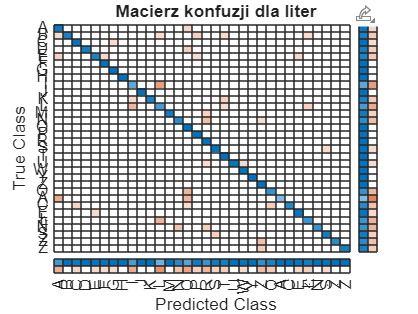


confChart.Title = 'Macierz konfuzji dla liter';
confChart.RowSummary = 'row-normalized';
confChart.ColumnSummary = 'column-normalized';